# Lab4

## Part 2 **CFO Estimation and correction **

clear; clc; close all;

%% =========================================================================
% 【Part 1 模擬】產生簡化版 Wi-Fi-Based OFDM 訊號與通道傳輸
% =========================================================================
% 基本參數設定
fs = 10e6;           % OFDM sample rate = 10 MHz [cite: 30]
fc = 2.4e9;          % 載波頻率，假設為 2.4 GHz [cite: 29]
N_fft = 64;          % FFT size = 64 [cite: 28]
N_cp = 16;           % CP size = 16 [cite: 28]
num_sym = 100;       % Part 2 使用 100 個 OFDM data symbols [cite: 110]
subcarriers = -26:26;% 使用的子載波範圍 [cite: 112]
data_sc = setdiff(-26:26, [-21, -7, 0, 7, 21]); % 扣除 Pilot 與 DC [cite: 31]
pilot_sc = [-21, -7, 7, 21];

% 1. 產生 STS (Short Training Symbol) - 簡化產生 10 個週期，每個 16 samples
sts_time = randn(16,1) + 1i*randn(16,1); 
tx_STS = repmat(sts_time, 10, 1); % 共 160 samples

% 2. 產生 LTS (Long Training Symbol) - 2 個週期 (64) + CP (32)
lts_freq = zeros(N_fft, 1);
lts_freq(33 + subcarriers(subcarriers~=0)) = sign(randn(52,1)); % BPSK LTS
lts_time = ifft(ifftshift(lts_freq)) * sqrt(N_fft);
tx_LTS = [lts_time(end-31:end); lts_time; lts_time]; % 共 160 samples

% 3. 產生 100 個 OFDM Data Symbols (4-QAM data, BPSK pilots) [cite: 32, 47]
tx_data_time = zeros((N_fft + N_cp)*num_sym, 1);
tx_sym_matrix = zeros(N_fft, num_sym);
for k = 1:num_sym
    sym_freq = zeros(N_fft, 1);
    % Data tones: 4-QAM
    sym_freq(33 + data_sc) = (sign(randn(48,1)) + 1i*sign(randn(48,1))) / sqrt(2);
    % Pilot tones: BPSK
    sym_freq(33 + pilot_sc) = sign(randn(4,1));
    tx_sym_matrix(:, k) = sym_freq; % 儲存未來的比對標準
    
    % IFFT 與加入 CP [cite: 12]
    time_domain = ifft(ifftshift(sym_freq)) * sqrt(N_fft);
    tx_data_time((k-1)*(N_fft+N_cp)+1 : k*(N_fft+N_cp)) = [time_domain(end-N_cp+1:end); time_domain];
end

% 組合傳送訊號 (Frame)
tx_frame = [tx_STS; tx_LTS; tx_data_time];
t = (0:length(tx_frame)-1).' / fs;

% 模擬通道 (加入 Multipath 與 AWGN)
h = [0.8; 0.2*exp(-1i*pi/4); 0.1*exp(1i*pi/3)]; % 簡單的多路徑通道
rx_clean = filter(h, 1, tx_frame);
rx_sig = awgn(rx_clean, 25, 'measured');

### (1) Add a 5 ppm artificial CFO

% --- (1) 加入 5 ppm 人為 CFO，並使用兩段 LTS 估測通道 ---
ppm = 5;
true_cfo = ppm * 1e-6 * fc; % 5 ppm CFO [cite: 110]
rx_cfo = rx_sig .* exp(1i * 2 * pi * true_cfo * t); % 加入 CFO

% 假設完美 Synchronization，抓取 LTS 位置 (STS長度為 160)
rx_LTS_part = rx_cfo(161:320); 
rx_LTS1 = rx_LTS_part(33:96);   % 取出第一個 LTS (避開 32 samples 的 CP)
rx_LTS2 = rx_LTS_part(97:160);  % 取出第二個 LTS

% 轉換至頻域進行通道估測 [cite: 111]
H_est1 = fftshift(fft(rx_LTS1) / sqrt(N_fft)) ./ lts_freq;
H_est2 = fftshift(fft(rx_LTS2) / sqrt(N_fft)) ./ lts_freq;

% Plot (1): 繪製 magnitude 與 phase [cite: 112]
sc_idx = subcarriers + 33; 
figure('Name', '(1) Channel Estimation with CFO');
subplot(2,1,1);
plot(subcarriers, abs(H_est1(sc_idx)), '-o', subcarriers, abs(H_est2(sc_idx)), '-x');
title('(1) Channel Magnitude (With 5ppm CFO)'); xlabel('Subcarrier Index'); ylabel('Magnitude'); legend('LTS 1', 'LTS 2'); grid on;
subplot(2,1,2);
plot(subcarriers, angle(H_est1(sc_idx)), '-o', subcarriers, angle(H_est2(sc_idx)), '-x');
title('(1) Channel Phase (With 5ppm CFO)'); xlabel('Subcarrier Index'); ylabel('Phase (rad)'); legend('LTS 1', 'LTS 2'); grid on;
% [觀察] 因 CFO 造成的相位旋轉，LTS2 的相位會整體比 LTS1 偏移一固定角度 [cite: 113]。

### (2) Use the estimated channel in (1) for equalization

% --- (2) 未校正 CFO 下的 Equalization ---
rx_data_part = rx_cfo(321:end);
rx_data_eq_no_cfo = zeros(48, num_sym);
for k = 1:num_sym
    sym_time = rx_data_part((k-1)*(N_fft+N_cp) + N_cp + 1 : k*(N_fft+N_cp));
    sym_freq = fftshift(fft(sym_time) / sqrt(N_fft));
    % 使用第一個 LTS 估測的通道進行等化 [cite: 114]
    eq_freq = sym_freq(sc_idx) ./ H_est1(sc_idx); 
    % 取出 Data tones
    rx_data_eq_no_cfo(:, k) = eq_freq(ismember(subcarriers, data_sc));
end
figure('Name', '(2) Constellation without CFO Correction');
plot(rx_data_eq_no_cfo(:), '.', 'MarkerSize', 10);
title('(2) Received Constellation without CFO Correction'); grid on; axis square;
% [觀察] 星象圖呈現甜甜圈狀/同心圓擴散，因為 CFO 導致每個 symbol 的相位持續旋轉 [cite: 115]。

### (3) Estimate the CFO from the received frame using two consecutive STS

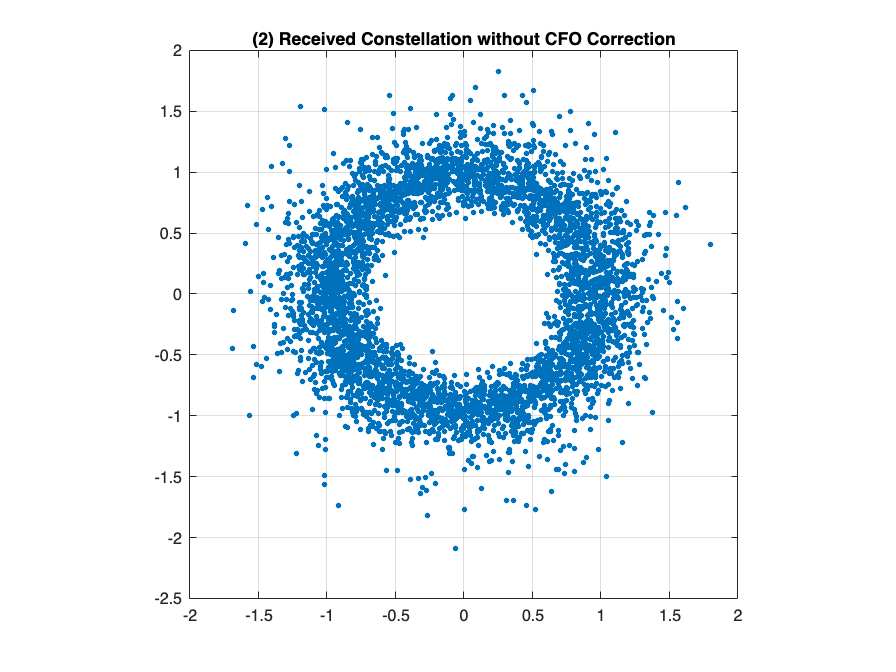

% --- (3) 使用 STS 估測 CFO ---
% 1. 使用連續兩個 STS (長度16) [cite: 116]
rx_STS = rx_cfo(1:160);

cfo_est_sts_consec = angle(sum(conj(rx_STS(1:16)) .* rx_STS(17:32))) / (2*pi*16/fs);
fprintf('(3) 兩連續 STS 估測之 CFO: %.2f Hz\n', cfo_est_sts_consec);

% 2. 使用第 8 與第 10 個 STS (不連續，間隔 32 samples) [cite: 117, 118]
cfo_est_sts_non_consec = angle(sum(conj(rx_STS(113:128)) .* rx_STS(145:160))) / (2*pi*32/fs);
fprintf('(3) 不連續(8th & 10th) STS 估測之 CFO: %.2f Hz\n', cfo_est_sts_non_consec);

### (4) Estimate the CFO from the received frame using two consecutive LTS

% --- (4) 使用 LTS 估測 CFO 並比較誤差 ---

(3) 兩連續 STS 估測之 CFO: 9025.53 Hz


% LTS 週期為 64 samples [cite: 120]
cfo_est_lts = angle(sum(conj(rx_LTS1) .* rx_LTS2)) / (2*pi*64/fs);
cfo_error = abs(true_cfo - cfo_est_lts);
fprintf('(4) 兩連續 LTS 估測之 CFO: %.2f Hz (True: %.2f Hz)\n', cfo_est_lts, true_cfo);

(3) 不連續(8th & 10th) STS 估測之 CFO: 12459.16 Hz


fprintf('(4) 估測誤差: %.2f Hz\n', cfo_error); % [cite: 121]

### (5) Using the estimated CFO in (4), apply the CFO correction to the waveform


% --- (5) 套用 CFO 校正並重新估測通道 ---
rx_corrected = rx_cfo .* exp(-1i * 2 * pi * cfo_est_lts * t); % 校正 CFO [cite: 122]
rx_LTS_corr = rx_corrected(161:320);
rx_LTS1_corr = rx_LTS_corr(33:96);

(4) 兩連續 LTS 估測之 CFO: 11884.39 Hz (True: 12000.00 Hz)


rx_LTS2_corr = rx_LTS_corr(97:160);

(4) 估測誤差: 115.61 Hz



H_est1_corr = fftshift(fft(rx_LTS1_corr) / sqrt(N_fft)) ./ lts_freq;
H_est2_corr = fftshift(fft(rx_LTS2_corr) / sqrt(N_fft)) ./ lts_freq;

figure('Name', '(5) Channel Estimation after CFO Correction');
subplot(2,1,1);
plot(subcarriers, abs(H_est1_corr(sc_idx)), '-o', subcarriers, abs(H_est2_corr(sc_idx)), '-x');
title('(5) Channel Magnitude (After CFO Correction)'); xlabel('Subcarrier Index'); ylabel('Magnitude'); legend('LTS 1', 'LTS 2'); grid on;
subplot(2,1,2);
plot(subcarriers, angle(H_est1_corr(sc_idx)), '-o', subcarriers, angle(H_est2_corr(sc_idx)), '-x');
title('(5) Channel Phase (After CFO Correction)'); xlabel('Subcarrier Index'); ylabel('Phase (rad)'); legend('LTS 1', 'LTS 2'); grid on;
% [觀察] 校正後，LTS1 與 LTS2 的相位曲線幾乎重疊，代表主要 CFO 已被消除 [cite: 125]。

### (6) Use the estimated channel in (5) for equalization

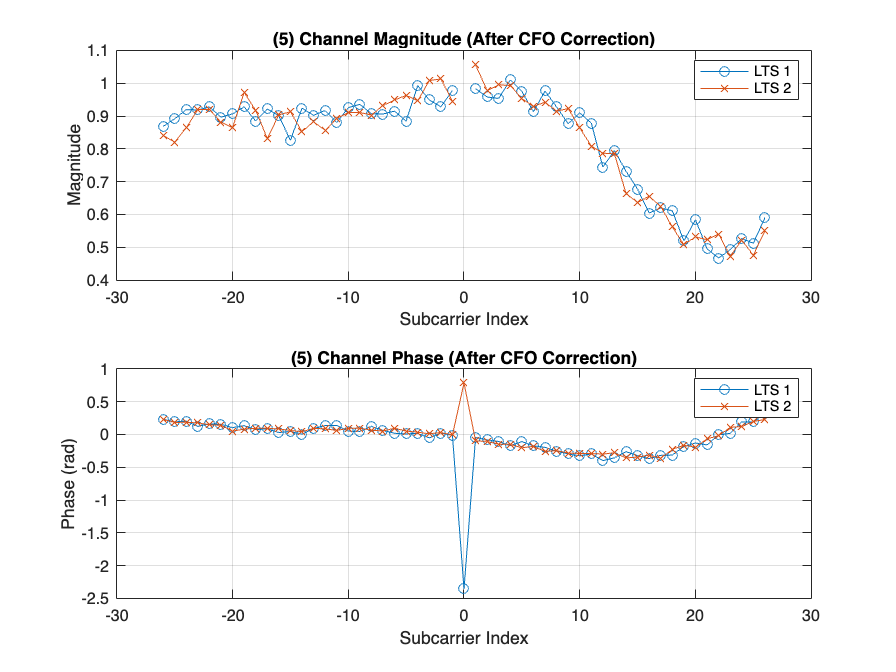

% --- (6) 校正後的 Equalization ---
rx_data_part_corr = rx_corrected(321:end);
rx_data_eq_corr = zeros(48, num_sym);
sym_freq_all = zeros(length(subcarriers), num_sym);

for k = 1:num_sym

    sym_time = rx_data_part_corr((k-1)*(N_fft+N_cp) + N_cp + 1 : k*(N_fft+N_cp));
    sym_freq = fftshift(fft(sym_time) / sqrt(N_fft));
    eq_freq = sym_freq(sc_idx) ./ H_est1_corr(sc_idx); % [cite: 126]
    sym_freq_all(:, k) = eq_freq; 
    rx_data_eq_corr(:, k) = eq_freq(ismember(subcarriers, data_sc));
end
figure('Name', '(6) Constellation After Initial CFO Correction');
plot(rx_data_eq_corr(:), '.', 'MarkerSize', 10);
title('(6) Received Constellation After Initial CFO Correction'); grid on; axis square;
% [觀察] 4-QAM 的四個叢集出現，但可能稍微被拉長或仍有輕微旋轉，這是因為存在 Residual CFO 隨時間累積 [cite: 127]。

### (7) Use the four pilot tones to track the residual CFO

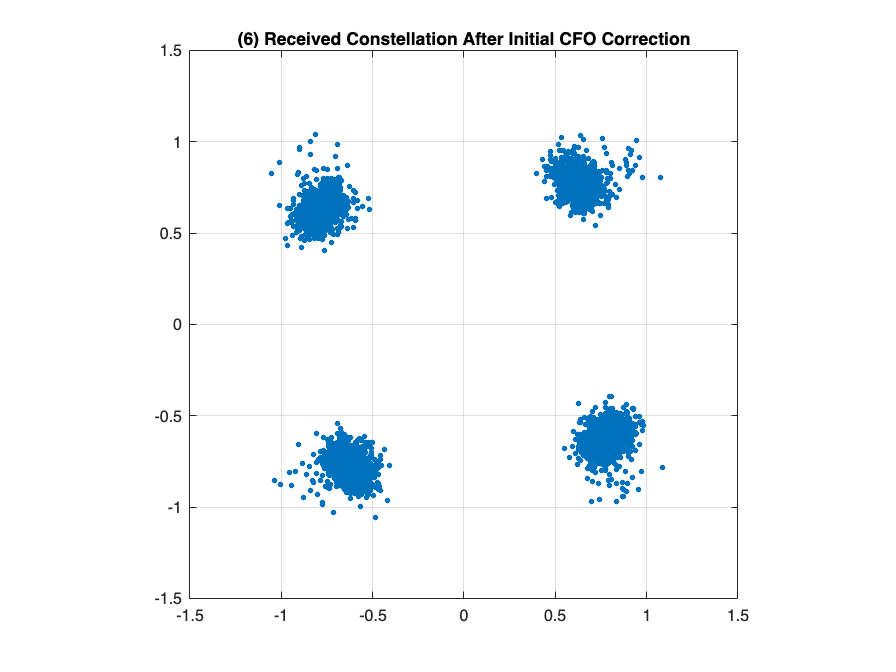

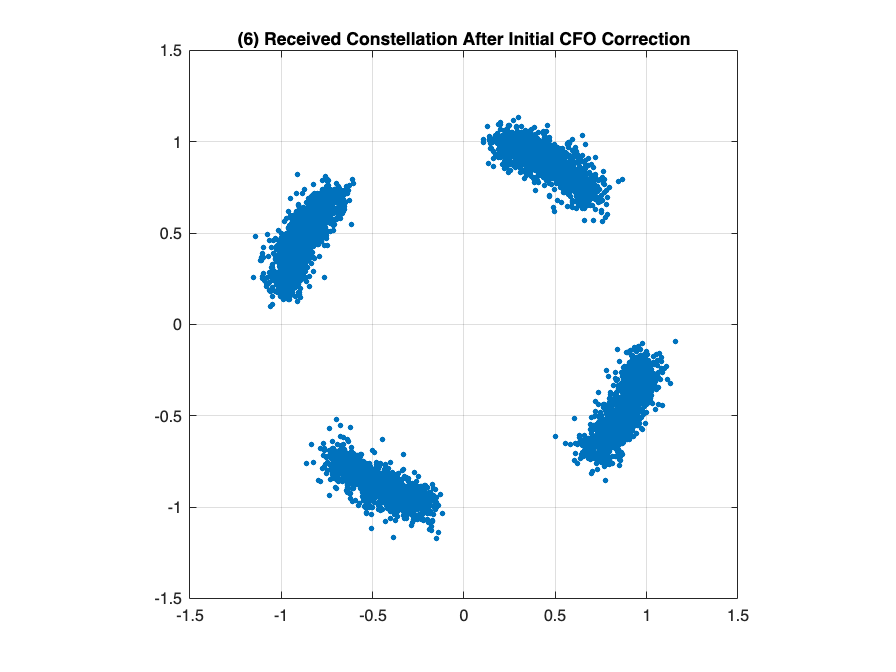

% --- (7) 利用 Pilot Tones 追蹤 Residual CFO ---
rx_data_eq_final = zeros(48, num_sym);
pilot_idx_in_sc = find(ismember(subcarriers, pilot_sc));
data_idx_in_sc = find(ismember(subcarriers, data_sc));


for k = 1:num_sym
    % 提取 Equalized 後的 Pilots
    rx_pilots = sym_freq_all(pilot_idx_in_sc, k);
    tx_pilots = tx_sym_matrix(33 + pilot_sc, k); % 原始傳送的 BPSK pilots
    
    % 計算殘留相位誤差 [cite: 128]
    phase_diff = angle(sum(rx_pilots .* conj(tx_pilots))); 
    
    % 修正 Data tones
    rx_data_eq_final(:, k) = sym_freq_all(data_idx_in_sc, k) * exp(-1i * phase_diff);
end
figure('Name', '(7) Constellation After Pilot Tracking');
plot(rx_data_eq_final(:), '.', 'MarkerSize', 10);
title('(7) Constellation After Residual CFO Tracking'); grid on; axis square;
% [觀察] 經由 Pilot 修正後，星象圖變得非常集中且清晰，Residual CFO 的緩慢旋轉被成功補償 [cite: 129]。

### (8) Increase the artificial CFO

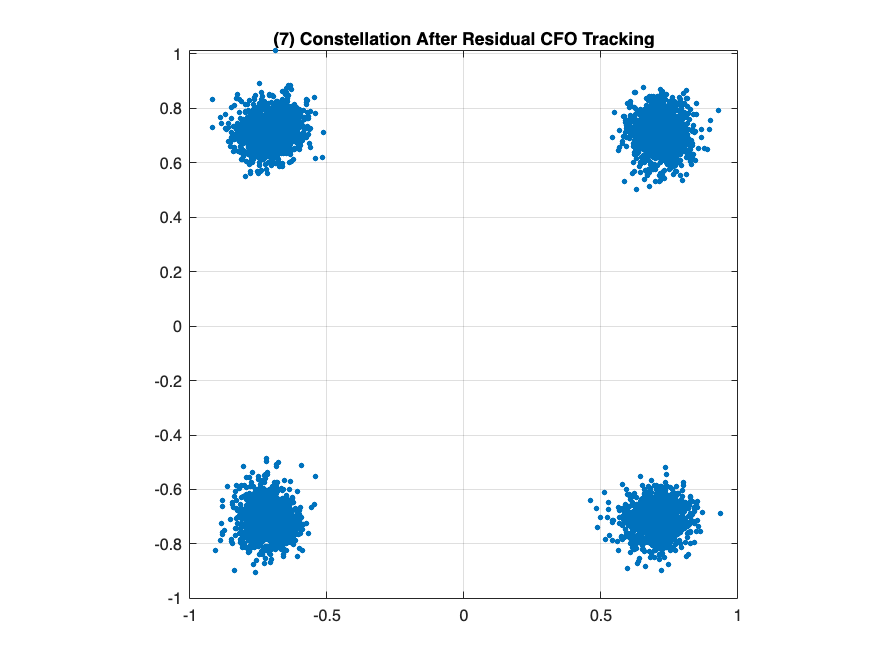

% --- (8) 測試 CFO 演算法的極限 (Scatter Plot) ---
test_ppm = -100:5:100; % 測試範圍
est_cfo_list = zeros(size(test_ppm));
true_cfo_list = test_ppm * 1e-6 * fc;

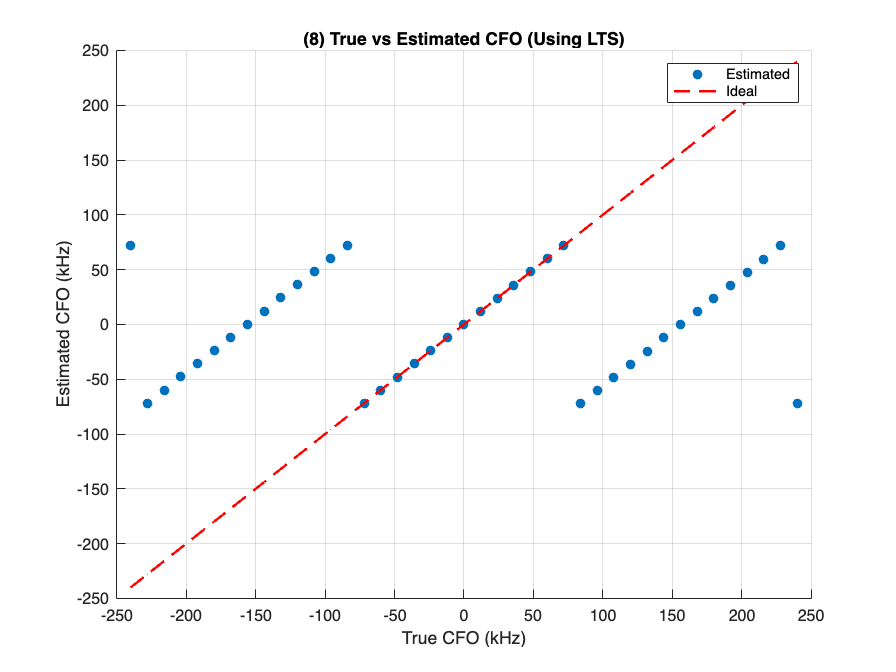


for i = 1:length(test_ppm)
    % 重複模擬流程
    temp_cfo = true_cfo_list(i);
    temp_rx = rx_sig .* exp(1i * 2 * pi * temp_cfo * t);
    
    % 以 LTS 估計為例 (距離 64 samples)
    temp_LTS1 = temp_rx(161+32 : 161+32+63);
    temp_LTS2 = temp_rx(161+32+64 : 161+32+127);
    est_cfo_list(i) = angle(sum(conj(temp_LTS1) .* temp_LTS2)) / (2*pi*64/fs); % [cite: 130, 131]
end

figure('Name', '(8) True vs Estimated CFO');
scatter(true_cfo_list/1e3, est_cfo_list/1e3, 'filled'); hold on;
plot(true_cfo_list/1e3, true_cfo_list/1e3, 'r--', 'LineWidth', 1.5);
title('(8) True vs Estimated CFO (Using LTS)');
xlabel('True CFO (kHz)'); ylabel('Estimated CFO (kHz)'); grid on; legend('Estimated', 'Ideal');
% [最大可校正 CFO]: 從圖可知當真實 CFO 超過 ±(fs / (2*64)) = ±78.125 kHz 時會產生 Phase wrap (相位纏繞)，因此這是純 LTS 估測的極限 [cite: 132]。